Lx = 1;
Ly = 1;
n_x = 101;
n_y = 101;
u0 = 1;
del_x = Lx/(n_x-1);
del_y = Ly/(n_y-1);
Re = 100;
del_t = 0.01;
pho = 1;

[vor_array, stream_func, u_array, v_array, iteration] = vorticity_eqn(Lx, Ly, n_x, n_y, u0, del_t, Re)

vor_array =          0   -0.0017   -0.0054   -0.0094   -0.0122   -0.0133   -0.0122   -0.0088   -0.0031    0.0048    0.0149    0.0269    0.0408    0.0564    0.0735    0.0920    0.1117    0.1324    0.1540    0.1764    0.1995    0.2231    0.2471    0.2714    0.2959    0.3205    0.3452    0.3698    0.3942    0.4184    0.4423    0.4658    0.4888    0.5112    0.5330    0.5541    0.5743    0.5937    0.6122    0.6295    0.6458    0.6608    0.6746    0.6870    0.6979    0.7073    0.7151    0.7213    0.7258    0.7285
   -0.0017   -0.0021   -0.0025   -0.0028   -0.0024   -0.0009    0.0022    0.0069    0.0134    0.0217    0.0318    0.0435    0.0569    0.0716    0.0878    0.1051    0.1235    0.1429    0.1631    0.1841    0.2056    0.2276    0.2501    0.2728    0.2957    0.3188    0.3418    0.3648    0.3876    0.4102    0.4325    0.4544    0.4758    0.4966    0.5169    0.5364    0.5552    0.5731    0.5901    0.6061    0.6210    0.6347    0.6473    0.6585    0.6684    0.6768    0.6838    0.6892    0.6

stream_func =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

u_array =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0002   -0.0003   -0.0005   -0.0006   -0.0008   -0.0010   -0.0012   -0.0014   -0.0016   -0.0018   -0.0020   -0.0023   -0.0025   -0.0027   -0.0030   -0.0032   -0.0034   -0.0037   -0.0039   -0.0041   -0.0044   -0.0046   -0.0048   -0.0050   -0.0053   -0.0055   -0.0057   -0.0058   -0.0060   -0.0062   -0.0063   -0.0065   -0.0066   -0.0067   -0.0068   -0.0069   -0.0070   -0.0071   -0.007

v_array =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.000

iteration = 1143

iteration

iteration = 1143

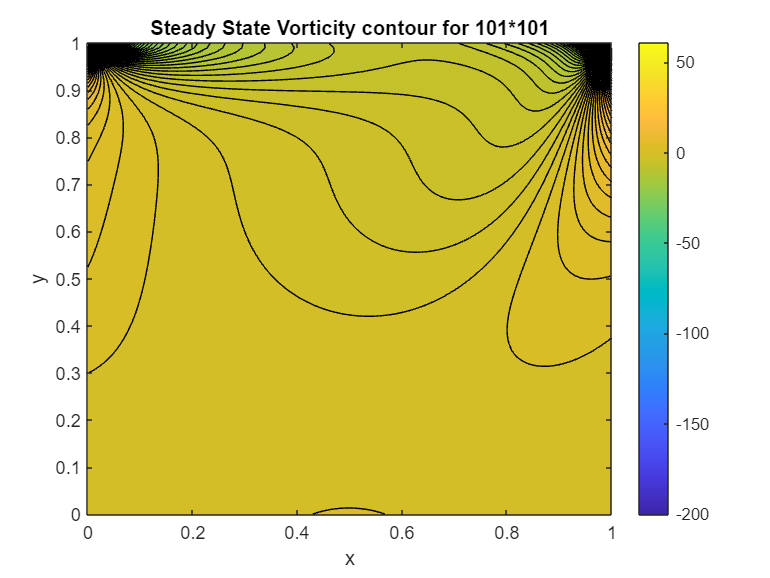

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, vor_array, 200, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State Vorticity contour for 101*101');
saveas(gcf, 'Vor101.png');

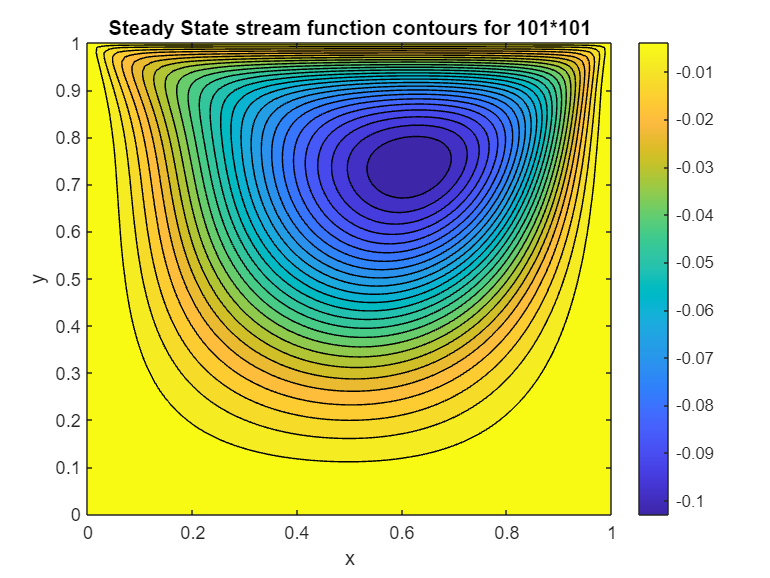

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, stream_func, 25, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State stream function contours for 101*101');
saveas(gcf, 'stream101.png');

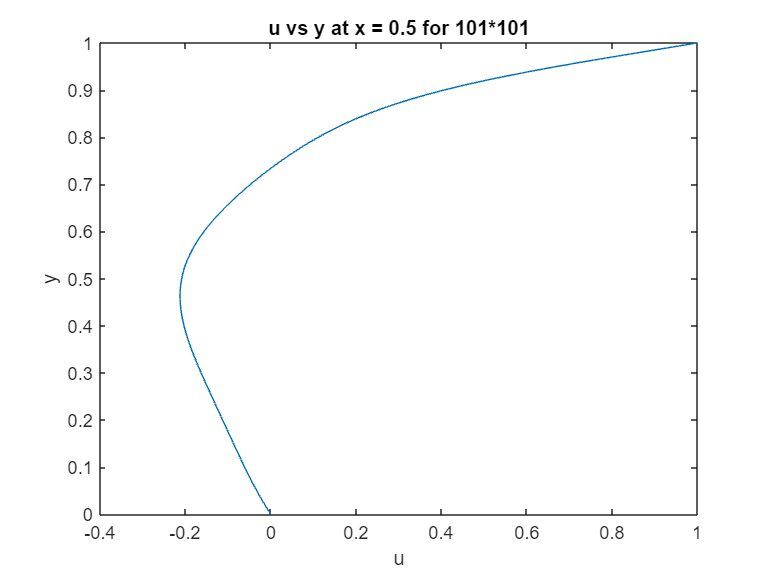

% Define y values at the desired interval
y_values = (0:del_y:Ly)';

% Extract the relevant column from u_array
u_column = u_array(:, (n_x+1)/2);

% Plot u_column against y_values
plot(u_column, y_values);
xlabel('u');
ylabel('y');
title('u vs y at x = 0.5 for 101*101')
saveas(gcf, 'uvsy101.png');

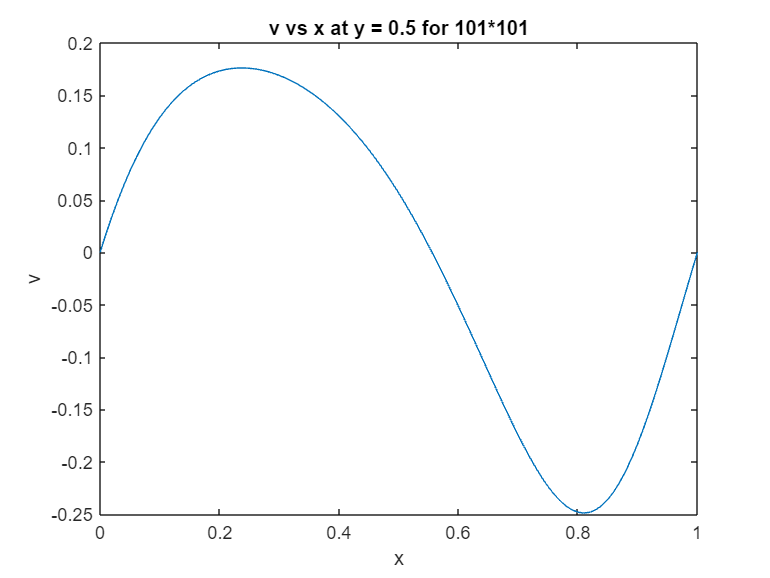

% Define y values at the desired interval
x_values = (0:del_x:Lx)';

% Extract the relevant column from u_array
v_row = v_array((n_y+1)/2, :);

% Plot u_column against y_values
plot(x_values, v_row);
xlabel('x');
ylabel('v');
title('v vs x at y = 0.5 for 101*101')
saveas(gcf, 'vvsx101.png');

pressure_array = cal_pressure(stream_func, Lx, Ly, 1);
pressure_array

pressure_array =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002  

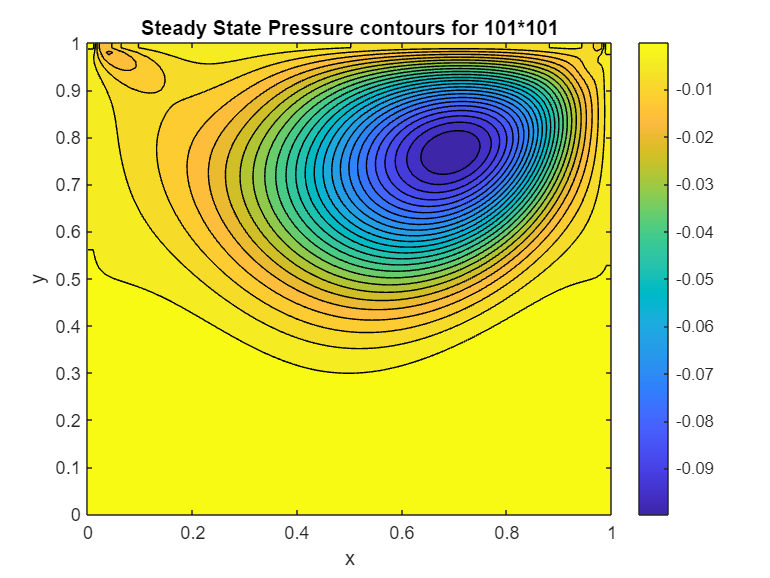

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, pressure_array, 25, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State Pressure contours for 101*101');
saveas(gcf, 'pressure101.png');